# Task 3.3

clc;
clear;
close all;

## Load Data

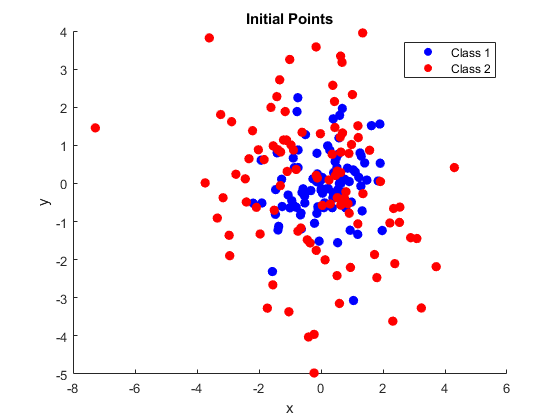

data = load("data33.mat");
X = data.X;
figure()
scatter(X(1,1:100), X(2,1:100), 50, 'blue', 'filled')
hold on;
scatter(X(1,101:end), X(2,101:end), 50, 'red', 'filled')
title('Initial Points')
xlabel('x')
ylabel('y')
legend('Class 1', 'Class 2')

## KMeans Algorithm

K = 2 % Set the amount of Z's

K = 2

iter = 25 % Set the amount of iterations

iter = 25

Total distance for iteration : 1 was : 311.3731
Total distance for iteration : 2 was : 287.6565
Total distance for iteration : 3 was : 284.9631
Total distance for iteration : 4 was : 283.8109
Total distance for iteration : 5 was : 282.939
Total distance for iteration : 6 was : 281.9658
Total distance for iteration : 7 was : 281.3723
Total distance for iteration : 8 was : 281.2997
Total distance for iteration : 9 was : 281.1152
Total distance for iteration : 10 was : 281.0637
Total distance for iteration : 11 was : 281.0637
Total distance for iteration : 12 was : 281.0637
Total distance for iteration : 13 was : 281.0637
Total distance for iteration : 14 was : 281.0637
Total distance for iteration : 15 was : 281.0637
Total distance for iteration : 16 was : 281.0637
Total distance for iteration : 17 was : 281.0637
Total distance for iteration : 18 was : 281.0637
Total distance for iteration : 19 was : 281.0637
Total distance for iteration : 20 was : 281.0637
Total distance for iteration :

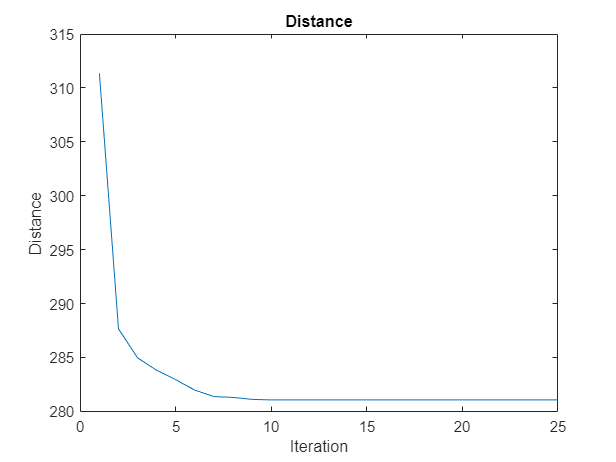

%======KMeans Result======%


C = 1×2 cell array
    {[1 2 4 5 8 9 10 11 14 15 16 17 18 20 21 22 25 29 30 32 34 38 40 41 42 43 45 46 47 48 49 50 52 53 54 56 57 59 60 61 62 64 65 66 67 68 69 70 71 72 75 76 78 81 82 84 85 86 88 89 90 92 94 95 96 97 98 101 102 103 107 108 109 111 112 113 114 117 118 119 120 122 124 126 127 129 130 132 136 137 139 141 143 144 146 147 148 150 152 153 154 156 158 162 164 166 169 173 175 176 177 179 180 185 186 189 191 193 195 198 199]}    {[3 6 7 12 13 19 23 24 26 27 28 31 33 35 36 37 39 44 51 55 58 63 73 74 77 79 80 83 87 91 93 99 100 104 105 106 110 115 116 121 123 125 128 131 133 134 135 138 140 142 145 149 151 155 157 159 160 161 163 165 167 168 170 171 172 174 178 181 182 183 184 187 188 190 192 194 196 197 200]}


Z =     0.8677   -1.4523
   -0.0081   -0.0752


[C, Z] = KMeans(X,K,iter) % Run the K-means algorithm

disp('%=========================%')

%=========================%


Class_Err = classificationError(X,Z); % Calculate the classification error
disp(['Total classification error: ' num2str(Class_Err * 100) '%'])

Total classification error: 43.5%


## Optimize KMeans

Total distance for iteration : 1 was : 714.1013
Total distance for iteration : 2 was : 574.9967
Total distance for iteration : 3 was : 584.3558
Total distance for iteration : 4 was : 601.0113
Total distance for iteration : 5 was : 601.0113
Total distance for iteration : 6 was : 601.0113
Total distance for iteration : 7 was : 601.0113
Total distance for iteration : 8 was : 601.0113
Total distance for iteration : 9 was : 601.0113
Total distance for iteration : 10 was : 601.0113
Total distance for iteration : 11 was : 601.0113
Total distance for iteration : 12 was : 601.0113
Total distance for iteration : 13 was : 601.0113
Total distance for iteration : 14 was : 601.0113
Total distance for iteration : 15 was : 601.0113
Total distance for iteration : 16 was : 601.0113
Total distance for iteration : 17 was : 601.0113
Total distance for iteration : 18 was : 601.0113
Total distance for iteration : 19 was : 601.0113
Total distance for iteration : 20 was : 601.0113
Total distance for iteration 

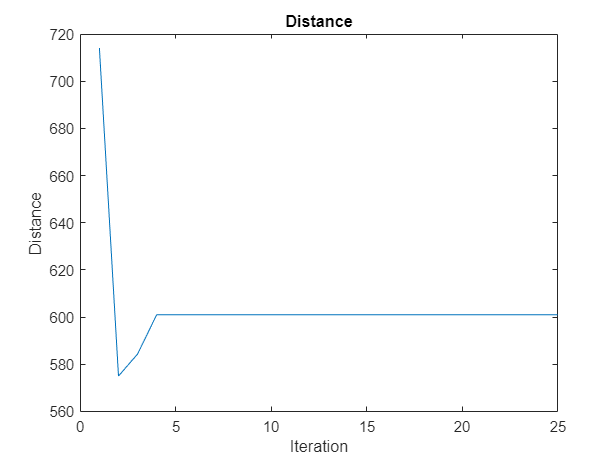

%======KMeans Result======%


C_b = 1×2 cell array
    {[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 95 96 97 98 99 100 101 106 107 108 109 110 111 113 114 115 116 118 119 120 121 123 124 128 129 130 131 132 134 136 139 140 141 143 144 145 146 148 149 150 151 153 154 155 156 158 161 162 163 164 165 166 167 168 171 172 173 175 176 178 179 180 181 183 184 185 186 190 191 194 195 196 198 199 200]}    {[94 102 103 104 105 112 117 122 125 126 127 133 135 137 138 142 147 152 157 159 160 169 170 174 177 182 187 188 189 192 193 197]}


Z_b =    -0.0051   -0.2776
    0.0618   -0.5404
    2.1781   15.4948


X_Norm = vecnorm(X,2,1);
X_New = [X ; X_Norm.^2];
[C_b, Z_b] = KMeans(X_New,K,iter) % Run the K-means algorithm

disp('%=========================%')

%=========================%


Class_Err_Opt = classificationError(X_New,Z_b); % Calculate the classification error
disp(['Total classification error: ' num2str(Class_Err_Opt * 100) '%'])

Total classification error: 35%


## Plot Results and Data

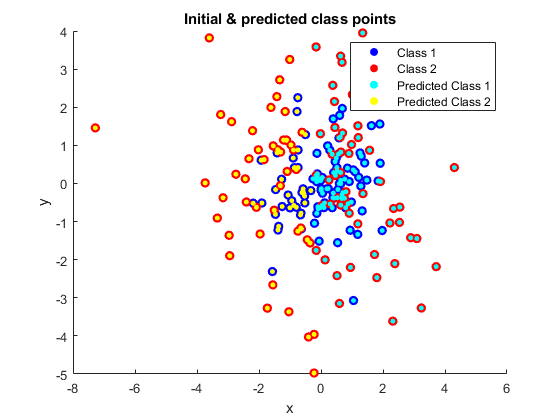

Plot_points = cell(1,K);
Plot_points_opt = cell(1,K);

for i=1:size(X,1)
    Class_ind = C{i};
    Class_ind_opt = C_b{i};
    Class_points = X(:, Class_ind);
    Class_points_opt = X(:,Class_ind_opt);
    Plot_points{i} = Class_points;
    Plot_points_opt{i} = Class_points_opt;
end

%===========PLOTS==========%
figure()
scatter(X(1,1:100), X(2,1:100), 50, 'blue', 'filled')
hold on;
scatter(X(1,101:end), X(2,101:end), 50, 'red', 'filled')
hold on;
scatter(Plot_points{1}(1,:), Plot_points{1}(2,:), 15, 'cyan', 'filled')
hold on;
scatter(Plot_points{2}(1,:), Plot_points{2}(2,:), 15, 'yellow', 'filled')
title('Initial & predicted class points')
xlabel('x')
ylabel('y')
legend('Class 1','Class 2', 'Predicted Class 1', 'Predicted Class 2')

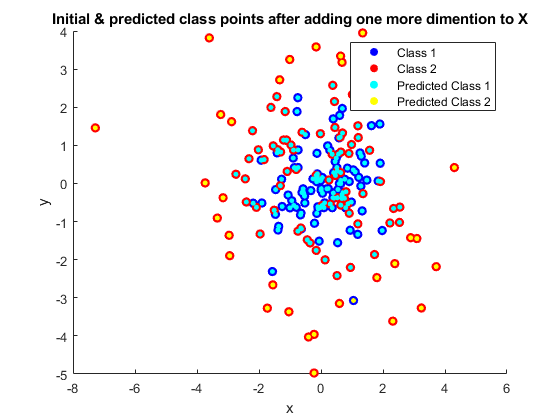

%===========PLOTS==========%
figure()
scatter(X(1,1:100), X(2,1:100), 50, 'blue', 'filled')
hold on;
scatter(X(1,101:end), X(2,101:end), 50, 'red', 'filled')
hold on;
scatter(Plot_points_opt{1}(1,:), Plot_points_opt{1}(2,:), 15, 'cyan', 'filled')
hold on;
scatter(Plot_points_opt{2}(1,:), Plot_points_opt{2}(2,:), 15, 'yellow', 'filled')
title('Initial & predicted class points after adding one more dimention to X')
xlabel('x')
ylabel('y')
legend('Class 1','Class 2', 'Predicted Class 1', 'Predicted Class 2')

## Functions

function [C, Z] = KMeans(X, K, iterations)
    % Choose randomly Z
    sz = [size(X,1), K];    
    Z = zeros(sz);    
    maxi = size(X,2);
    all_distances = zeros([1,iterations]);    
    
    for i=1:K % Initialize Centers
        center_ind = randi(maxi);
        center = X(:,center_ind);
        Z(:,i) = center ;
    end
        
    for iter=1:iterations % Run the K-means algorithm
        distance = 0;
        C = cell(1, K);     

        for i=1:K % Initialize C
            C{i} = [];
        end       

        for i=1:maxi % Classify data
            [~ , index] = min(vecnorm(Z'-X(:,i)',2,2));
            C{index}(end + 1) = i;                   
        end     

        for i=1:K % Calcualte the distance and change the centers
            class_indecies = C{i};
            class_points = X(:, class_indecies);

            distance = distance + sum(vecnorm(Z(:,i)' - class_points', 2, 2)); 
            Z(:,i) = mean(class_points,2);            
        end

        all_distances(iter) = distance;
        disp(['Total distance for iteration : ' num2str(iter) ' was : ' num2str(distance)])
    end
    %==========PLOT==========%
    figure()
    plot(all_distances)
    title('Distance')
    xlabel('Iteration')
    ylabel('Distance')
    disp('%======K-means Result======%')
end

function err = classificationError(X,Z)
    tot_err_1 = 0;
    tot_err_2 = 0;
    maxi = size(X,2);

    for i=1:maxi
        [~ , index] = min(vecnorm(Z'-X(:,i)',2,2));
        if index == 1 && i >=100
            tot_err_1 = tot_err_1 + 1;

        elseif index == 2 && i<100
            tot_err_2 = tot_err_2 + 1;
        end
    end    
    err = (tot_err_1 + tot_err_2)/maxi;
end